# PTP轨迹规划 - 笛卡尔空间到关节空间

clear; clc; close all;

## 创建机器人模型（Modified DH参数）

% 定义连杆长度
d4_val = 0.187 + 0.063; 

% 建立 Standard DH 模型
L(1) = Link('revolute', 'd', 0.12202, 'a', 0.1, 'alpha', -pi/2, 'standard');
L(2) = Link('revolute', 'd', 0, 'a', 0.25, 'alpha', 0, 'standard', 'offset', -pi/2);
L(3) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard', 'offset', pi);
L(4) = Link('revolute', 'd', d4_val, 'a', 0, 'alpha', -pi/2, 'standard');
L(5) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard');
L(6) = Link('revolute', 'd', 0.0595, 'a', 0, 'alpha', 0, 'standard');
EpsonC3 = SerialLink(L, 'name', 'Epson C3 A601', 'base', transl(0,0,0.198));
file_path = '.\EpsonC3A601_SW\';

## 设置工作空间

workspace = [-0.5 0.5 -0.5 0.5 0 0.8];
EpsonC3.plotopt = {'workspace', workspace, 'scale', 0.5};

## 定义笛卡尔空间中的起始点和目标点

% 点1：初始位置
T_start = transl(0.3, -0.2, 0.500) * rpy2tr(0, pi, 0, 'arm');
% 点2：目标位置
T_goal = transl(0.1, 0.4, 0.2) * rpy2tr(0, pi, 0, 'arm');

## 使用逆运动学求解关节角度

定义关节角度限制

qlim = [
    -170/180*pi, 170/180*pi;    % 关节1限制
    -160/180*pi, 65/180*pi; % 关节2限制
    -51/180*pi, 225/180*pi; % 关节3限制
    -200/180*pi, 200/180*pi;    % 关节4限制
    -135/180*pi, 135/180*pi;    % 关节5限制
    -2*pi, 2*pi;    % 关节6限制
];

% 设置初始关节角度猜测
q0 = [0, 0, 0, 0, 0, 0];

% 使用逆运动学求解起始点和目标点关节角度
q_start = EpsonC3.ikine(T_start, 'q0', q0, 'mask', [1 1 1 1 1 1]);
q_goal = EpsonC3.ikine(T_goal, 'q0', q0, 'mask', [1 1 1 1 1 1]);

% 检查是否成功求解逆运动学
if any(isnan(q_start)) || any(isnan(q_goal))
    error('逆运动学求解失败！请检查目标位姿是否在机器人的工作空间内。');
end

## PTP轨迹规划（关节空间五次多项式插值）

设置轨迹参数

t_total = 5;  % 总运动时间（秒）
t_samples = 100;  % 时间采样点数
t = linspace(0, t_total, t_samples);

% 使用jtraj函数进行五次多项式插值（保证速度、加速度连续）
[q_ptp, qd_ptp, qdd_ptp] = jtraj(q_start, q_goal, t);

## 运动学正解验证

计算轨迹上每个点的末端位姿

T_traj = zeros(4, 4, length(t));
for i = 1:length(t)
    T_traj(:,:,i) = EpsonC3.fkine(q_ptp(i,:));
end

## 可视化结果

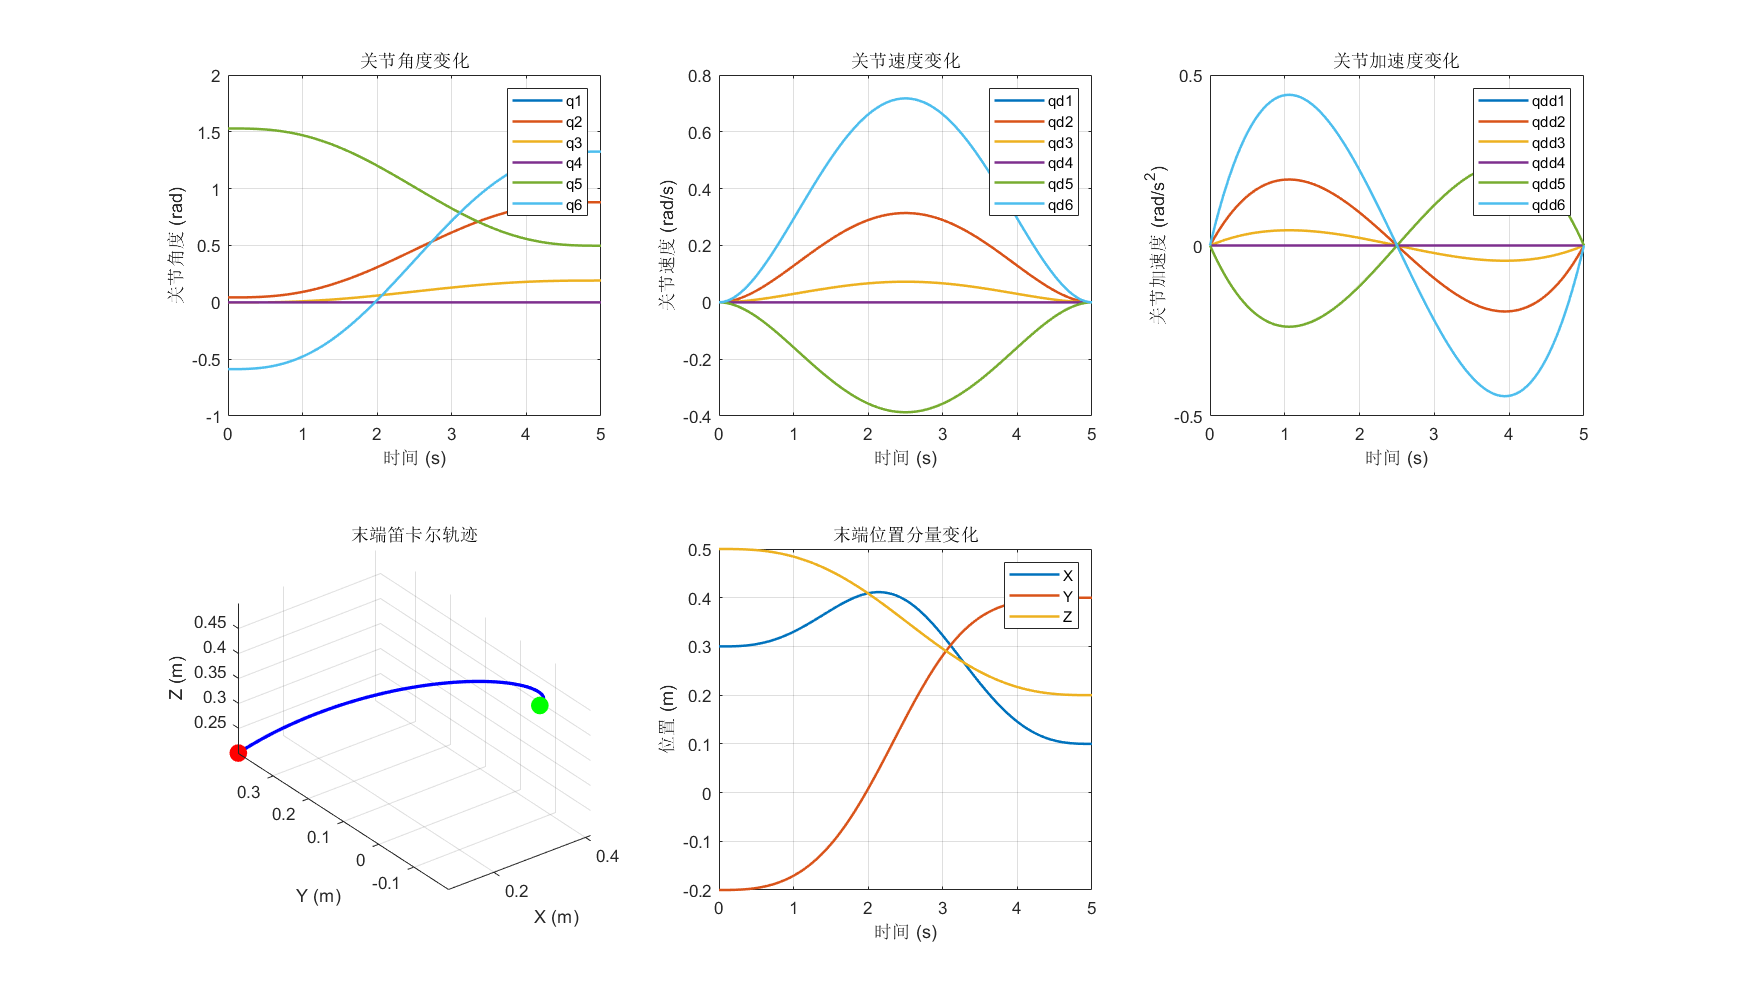

figure('Position', [100, 100, 1400, 800]);

% 1. 关节角度变化曲线
subplot(2,3,1);
plot(t, q_ptp, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('关节角度 (rad)');
title('关节角度变化');
legend('q1', 'q2', 'q3', 'q4', 'q5', 'q6');
grid on;

% 2. 关节速度变化曲线
subplot(2,3,2);
plot(t, qd_ptp, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('关节速度 (rad/s)');
title('关节速度变化');
legend('qd1', 'qd2', 'qd3', 'qd4', 'qd5', 'qd6');
grid on;

% 3. 关节加速度变化曲线
subplot(2,3,3);
plot(t, qdd_ptp, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('关节加速度 (rad/s^2)');
title('关节加速度变化');
legend('qdd1', 'qdd2', 'qdd3', 'qdd4', 'qdd5', 'qdd6');
grid on;

% 4. 末端笛卡尔轨迹
subplot(2,3,4);
% 提取末端位置
pos_traj = zeros(length(t), 3);
for i = 1:length(t)
    pos = transl(T_traj(:,:,i));
    pos_traj(i,:) = pos';
end
plot3(pos_traj(:,1), pos_traj(:,2), pos_traj(:,3), 'b-', 'LineWidth', 2);
hold on;
plot3(pos_traj(1,1), pos_traj(1,2), pos_traj(1,3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot3(pos_traj(end,1), pos_traj(end,2), pos_traj(end,3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('末端笛卡尔轨迹');
grid on;
axis equal;

% 5. 末端位置分量变化
subplot(2,3,5);
plot(t, pos_traj, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('位置 (m)');
title('末端位置分量变化');
legend('X', 'Y', 'Z');
grid on;

## 机器人运动动画（单独窗口）

close all;
figure('Position', [100, 100, 1280, 720], 'Name', 'PTP路径规划', 'Renderer','opengl'); % RTB直接渲染动画的话，只支持720P，再高会出现画面裁剪
title('PTP轨迹运动动画');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
axis(workspace); % 保证画面大小与工作空间一致
hold on;
% 绘制起止点
trplot(T_start, 'color', 'g', 'frame', 'Start', 'length', 0.1);
trplot(T_goal, 'color', 'r', 'frame', 'Goal', 'length', 0.1);
% 绘制机械臂动画
light('Position', [1, 1, -1], 'color', 'w'); % 打光，不然机械臂有点暗
light('Position', [1, 1, 1], 'color', 'w'); % 打光，不然机械臂有点暗
EpsonC3.plot3d(q_ptp, 'tilesize', 0.1, 'path', file_path, 'nowrist', 'trail', {'r', 'linewidth', 1}, 'workspace', workspace, 'scale', 0.5, 'fps', 20, ...
    'movie', '.\videos\cartesion_PTP.mp4');

Animate: saving video --> .\videos\cartesion_PTP.mp4 with profile 'MPEG-4'


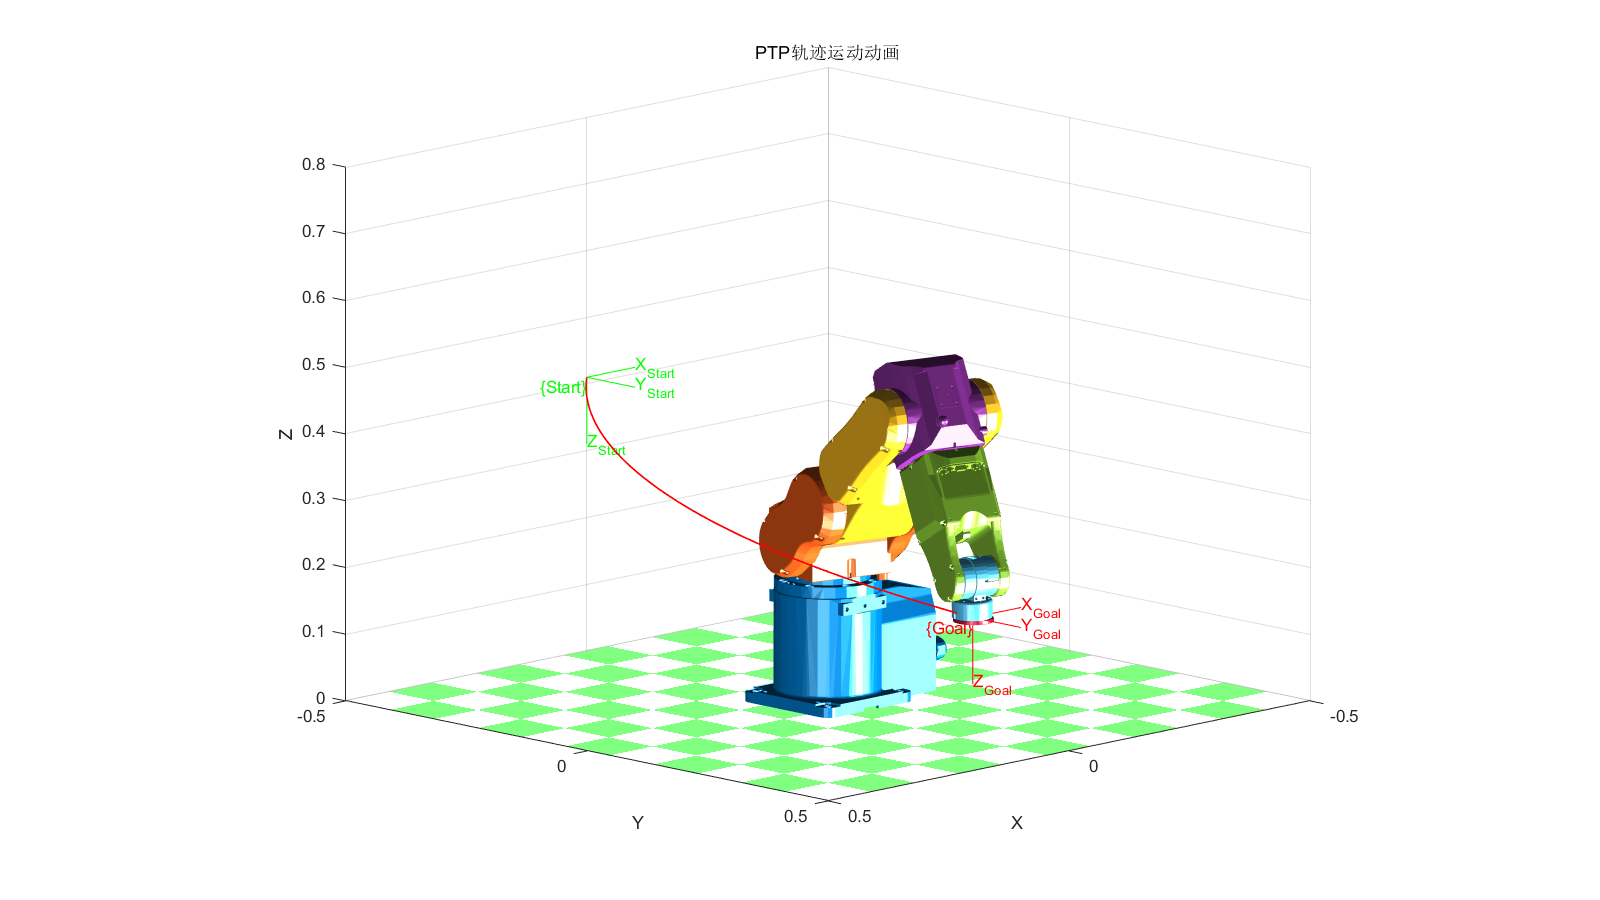

hold off;

## 轨迹优化评估

fprintf('========== PTP轨迹规划结果 ==========\n');

========== PTP轨迹规划结果 ==========


fprintf('起始关节角度: [%.3f, %.3f, %.3f, %.3f, %.3f, %.3f] rad\n', q_start);

起始关节角度: [-0.588, 0.043, -0.002, -0.000, 1.530, -0.588] rad


fprintf('目标关节角度: [%.3f, %.3f, %.3f, %.3f, %.3f, %.3f] rad\n', q_goal);

目标关节角度: [1.326, 0.881, 0.192, 0.000, 0.498, 1.326] rad


fprintf('总运动时间: %.2f s\n', t_total);

总运动时间: 5.00 s


fprintf('采样点数: %d\n', t_samples);

采样点数: 100



% 计算最大关节速度
max_qd = max(abs(qd_ptp), [], 1);
fprintf('\n最大关节速度 (rad/s):\n');


最大关节速度 (rad/s):


for i = 1:6
    fprintf('关节%d: %.3f\n', i, max_qd(i));
end

关节1: 0.718
关节2: 0.314
关节3: 0.073
关节4: 0.000
关节5: 0.387
关节6: 0.718



% 计算最大关节加速度
max_qdd = max(abs(qdd_ptp), [], 1);
fprintf('\n最大关节加速度 (rad/s²):\n');


最大关节加速度 (rad/s²):


for i = 1:6
    fprintf('关节%d: %.3f\n', i, max_qdd(i));
end

关节1: 0.442
关节2: 0.194
关节3: 0.045
关节4: 0.000
关节5: 0.238
关节6: 0.442



% 计算路径长度（关节空间）
path_length = 0;
for i = 2:length(t)
    path_length = path_length + norm(q_ptp(i,:) - q_ptp(i-1,:));
end
fprintf('\n关节空间路径长度: %.3f rad\n', path_length);


关节空间路径长度: 3.021 rad



% 检查关节限位
fprintf('\n关节限位检查:\n');


关节限位检查:


for i = 1:6
    if any(q_ptp(:,i) < qlim(i,1)) || any(q_ptp(:,i) > qlim(i,2))
        fprintf('警告: 关节%d超出限位范围 [%.2f, %.2f]\n', i, qlim(i,1), qlim(i,2));
    else
        fprintf('关节%d在限位范围内 [%.2f, %.2f]\n', i, qlim(i,1), qlim(i,2));
    end
end

关节1在限位范围内 [-2.97, 2.97]
关节2在限位范围内 [-2.79, 1.13]
关节3在限位范围内 [-0.89, 3.93]
关节4在限位范围内 [-3.49, 3.49]
关节5在限位范围内 [-2.36, 2.36]
关节6在限位范围内 [-6.28, 6.28]



% 计算末端位置误差
pos_error = norm(transl(T_traj(:,:,end)) - transl(T_goal));
fprintf('\n末端位置误差: %.6f m\n', pos_error);


末端位置误差: 0.000000 m
